# **EFTERÅR 2015 EKSAMEN**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**Lad den simultane tæthedsfunktion for to diskrete stokastiske variable X og Y være angivet som tabellen i opgavebeskrivelsen.**

## 1.1 MARGINALE TÆTHEDSFUNKTIONER

**Vis at de marginale tæthedsfunktionerfor X og Y er givet som i tabellerne i opgavebeskrivelsen.**


$$f_Y \left(y\right)=\sum_x f_{X,Y} \left(x,y\right),\;\;\;\;f_X \left(x\right)=\sum_y f_{X,Y} \left(x,y\right)$$


data = [
    [0,     1/12,   0   ];
    [2/12,  0,      2/12];
    [2/12,  1/12,   2/12];
    [0,     2/12,   0   ]
];

MarginalX = sum(data);
MarginalY = sum((data'));

TX = array2table(MarginalX, 'VariableNames',{'X1','X2','X3'}, 'RowNames',{'fX(x)'})

TX = 1×3 table
               X1         X2         X3   
             _______    _______    _______

    fX(x)    0.33333    0.33333    0.33333


x = sym(MarginalX)

$$x = \left(\begin{array}{ccc} \frac{1}{3} & \frac{1}{3} & \frac{1}{3} \end{array}\right)$$

TY = array2table(MarginalY, 'VariableNames',{'Y5','Y6','Y7', 'Y8'}, 'RowNames',{'fY(y)'})

TY = 1×4 table
                Y5         Y6         Y7         Y8   
             ________    _______    _______    _______

    fY(y)    0.083333    0.33333    0.41667    0.16667


y = sym(MarginalY)

$$y = \left(\begin{array}{cccc} \frac{1}{12} & \frac{1}{3} & \frac{5}{12} & \frac{1}{6} \end{array}\right)$$

## 1.2 FORVENTNINGSVÆRDI

**Vis at de i opgavebeskrivelsen givet udtryk er korrekt.**


$$E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x=x_i \right)$$


estimationX = 0;

for n = 1:length(MarginalX)
    estimationX = estimationX + (n * MarginalX(n));
end

disp("E[X] = " + estimationX);

E[X] = 2


offset = 4;
estimationY = 0;

for n = 1:length(MarginalY)
    estimationY = estimationY + ((n + offset) * MarginalY(n));
end

disp("E[Y] = " + estimationY);

E[Y] = 6.6667


offset = 4;
estimationXY = 0;

for n = 1:length(MarginalX)
    for j = 1:length(MarginalY)
        estimationXY = estimationXY + ((n * (j + offset)) * data(j, n));
    end
end

disp("E[XY] = " + estimationXY);

E[XY] = 13.3333


estimationXSquared = 0;

for n = 1:length(MarginalX)
    estimationXSquared = estimationXSquared + ((n^2) * MarginalX(n));
end

disp("E[X^2] = " + estimationXSquared);

E[X^2] = 4.6667


offset = 4;
estimationYSquared = 0;

for n = 1:length(MarginalY)
    estimationYSquared = estimationYSquared + ((n + offset)^2 * MarginalY(n));
end

disp("E[Y^2] = " + estimationYSquared);

E[Y^2] = 45.1667


## 1.3 KORRELATIONS KOEFFICIENT

**Hvad er korrelationskoefficienten for X og Y?**


$$\rho =\frac{E\left\lbrack \mathrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack }{\sigma_X \cdot \sigma_Y }$$



$$\sigma {\;}_X^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 ,\;\;\;\;\;\sigma {\;}_Y^2 =E\left\lbrack Y^2 \right\rbrack -E{\left\lbrack Y\right\rbrack }^2$$



$$\rho =\frac{E\left\lbrack \mathrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack \cdot E\left\lbrack Y\right\rbrack }{\sqrt{E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2 }\cdot \sqrt{E\left\lbrack Y^2 \right\rbrack -E{\left\lbrack Y\right\rbrack }^2 }}$$


upper = estimationXY - (estimationX * estimationY);

sigmaX = sqrt(estimationXSquared - estimationX^2);

sigmaY = sqrt(estimationYSquared - estimationY^2);

correlation = upper / (sigmaX * sigmaY);

disp("p = " + correlation);

p = 0


## 1.4 KORRELEREDE VARIABLE

**Er de stokastiske variable X og Y korrelerede?**

Da korrelationskoefficienten er lig med 0, er X og Y ukorrelerede.

## 1.5 UAFHÆNGIGHED

**Er de stokastiske variable X og Y uafhængige?**

if MarginalX(1) * MarginalY(1) == data(1, 1)
    disp("X og Y er uafhængige, da fx(x) * fy(y) er identisk med fxy(x, y)");
else
    disp("X og Y er ikke uafhængige, da fx(x) * fy(y) ikke er identisk med fxy(x, y)");
end

X og Y er ikke uafhængige, da fx(x) * fy(y) ikke er identisk med fxy(x, y)


## 1.6 BETINGET SANDSYNLIGHED

**Opskriv den betinget sandsynlighed for **

   
$$f_{X|Y} \left(x|y=6\right)$$


Den betinget sandsynlighed kan opskrives som


$$f_{X|Y} \left(x|y\right)=\frac{f_{X,Y} \left(x,y\right)}{f_X \left(x\right)}$$


for n = 1:3
    probabilityX(n) = data(6 - offset, n) / MarginalY(6 - offset);
    names(n) = cellstr(("X" + num2str(n)));
end

TP = array2table(probabilityX, 'VariableNames', names, 'RowNames',{'fX|Y(x|y)'})

TP = 1×3 table
                 X1     X2    X3 
                 ___    __    ___

    fX|Y(x|y)    0.5    0     0.5


prob = sym(probabilityX)

$$prob = \left(\begin{array}{ccc} \frac{1}{2} & 0 & \frac{1}{2} \end{array}\right)$$

# **2 STOKASTISKE PROCESSER**

**En diskret process er givet ved X(n) = w(n), w(n) angives desuden til at være i.i.d efter en uniform fordeling med w(n) ~ U(0, 10).**

## 2.1 SKITSERING AF REALISATION

**Skitser 10 samples af en realisation af processen X(n) for n = 1.. 10.**

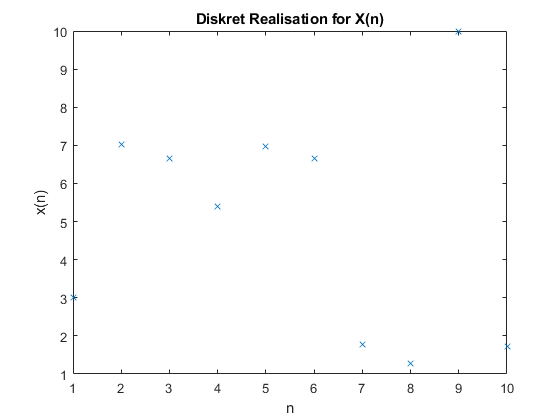

mu = 0;
sigma = 10;

realisation = sigma * rand(1, 10) + mu;

figure(1)
plot(1:length(realisation), realisation, 'x');
title('Diskret Realisation for X(n)')
xlabel('n')
ylabel('x(n)')

## 2.2 MIDDELVÆRDI OG VARIANS

**Bestem ensemble middelværdien og variansen for processen X(n).**


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack$$


da processen er uniform fordelt gælder følgende for $w=\;\mu \left(a,b\right)$


$$E\left\lbrack X\left(n\right)\right\rbrack =\frac{a+b}{2}$$


Som omskrevet bliver til


$$E\left\lbrack X\left(n\right)\right\rbrack =\frac{1}{2}\left(a+b\right)$$


ensembleMean = (1/2) * (mu + sigma);

disp("Ensemble middelværdien for processen er " + ensembleMean);

Ensemble middelværdien for processen er 5


for variansen af en uniform fordeling gælder følgende for $w=\;\mu \left(a,b\right)$

   
$$\mathrm{var}\left(w\right)=\frac{1}{12}{\left(b-a\right)}^2$$


ensembleVariance = (1/12) * (sigma - mu)^2;

disp("Ensemble variansen for processen er " + ensembleVariance);

Ensemble variansen for processen er 8.3333


sym(ensembleVariance)

$$ans = \frac{25}{3}$$

## 2.3 AUTOKORRELATION

**Bestem autokorrelationsfunktionen Rxx(t) for processen X(n) for t = 0.. 3.**

For korrelationen til n = 0 gælder der, at


$$R_{\mathrm{XX}} \left(n\right)=E\left\lbrack X\left(n\right)\cdot X\left(n\right)\right\rbrack$$


Da der for variansen gældet, at 


$$\mathrm{var}\left(X\right)=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$
 

Kan korrelation omskrives til følgende


$$R_{\mathrm{XX}} \left(n\right)=\mathrm{var}\left(X\right)+E{\left\lbrack X\right\rbrack }^2$$


n = 0;

correlation(n + 1) = ensembleVariance + ensembleMean^2;

Hvor der for autokorrelationen til n > 0 gælder, at


$$R_{\mathrm{XX}} \left(n\right)=E\left\lbrack X\left(n\right)\cdot X\left(n+1\right)\right\rbrack ,\;n>1$$


Kan omskrives til

   
$$R_{\mathrm{XX}} \left(n\right)=E\left\lbrack X\left(n\right)\right\rbrack \cdot E\left\lbrack X\left(n+1\right)\right\rbrack$$


da processen er uniform fordelt gælder følgende for $w=\;\mu \left(a,b\right)$


$$E\left\lbrack X\left(n\right)\right\rbrack =\frac{a+b}{2}$$


således bliver det til følgende


$$R_{\mathrm{XX}} \left(n\right)=\left(\frac{a+b}{2}\right)\cdot \left(\frac{a+b}{2}\right)={\left(\frac{a+b}{2}\right)}^2$$


w(n) og w(n + 1) er uafhængige grundet i.i.d.

for n = 1:3
    correlation(n + 1) = ((mu + sigma) / 2)^2;
end

correlation = sym(correlation)

$$correlation = \left(\begin{array}{cccc} \frac{100}{3} & 25 & 25 & 25 \end{array}\right)$$

## 2.4 PROCESSEN

**Angiv om processen er WSS (stationær i den bredde forstand) og om den er ergodisk.**

Da middelværdien $E\left\lbrack X\left(n\right)\right\rbrack$er uafhængig af n og konstant samt variancen er uafhængig af n og konstant, kan processen siges at være stationær i den bredde forstand.Samtidig er processen ergodisk da den ikke er tidsahængig samt middelværdien og variansen for ensemble ikke ændres. Disse værdier kan opnås ved en enkelt realisering og vil for flere realiseringer være den samme.

# **3 SANDSYNLIGHED**

**Laktoseintolerans er tilstede hos 20% af den finske befolkning. Hvis en finne har laktoseintolerans, vil en test give en positiv test i 90% af tilfældene. Hvis finnen ikke har sygdommen, vil testen give en positiv test i 30% af tilfældene.**

## **3.1 TOTAL SANDSYNLIGHED**

**Event A: Laktoseintolerent**

**Event B: Positiv Test**

$P\left(A\right)=0\ldotp 2$,  $P\left(B|A\right)=0\ldotp 9$,  $P\left(B|\overline{A} \right)=0\ldotp 3$

Den totale sandsynlighed kan findes udtryk som følgende: 


$$P\left(B\right)=\sum_{i=1}^n P\left(B\;|\;A_i \right)\cdot P\left(A_i \right)$$


Intolerant = 0.2;
IntolerantPositiveTest = 0.9;
NoIntolerantPositiveTest = 0.3;
NotIntolerant = 1 - Intolerant;

PositiveTest = (IntolerantPositiveTest * Intolerant) + (NoIntolerantPositiveTest * NotIntolerant);

disp("Den totale sandsynlighed for en positiv test er: " + PositiveTest);

Den totale sandsynlighed for en positiv test er: 0.42


## 3.2 BETINGET SANDSYNLIGHED

For at finde sandsynligheden for at have en positiv test same også at have sygdommen kan findes ved at anvende bayes formel som nedenstående: 


$$P\left(A|B\right)=\frac{P\left(B|A\right)\cdot P\left(A\right)}{P\left(B\right)}$$


IntolerantGivenPositiveTest = (IntolerantPositiveTest * Intolerant) / PositiveTest;

disp("Sandsynligheden for at en finne har en positiv test og samtidig har sygdommen er: " + IntolerantGivenPositiveTest);

Sandsynligheden for at en finne har en positiv test og samtidig har sygdommen er: 0.42857


# **4 STATISTIK**

## **4.1 PLOT**

**Plot data fra tabellen, og optegn den bedste rette linie gennem punkterne ved at bestemme skæringen med y-aksen og hældningen af den lineære model. Angiv hvilken metode, der er anvendt til at finde den lineære model.**

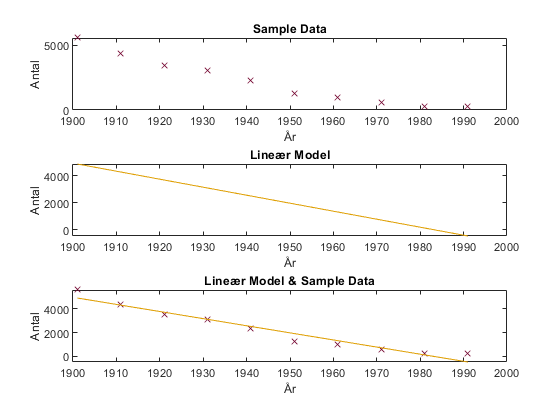

Year = [1901, 1911, 1921, 1931, 1941, 1951, 1961, 1971, 1981, 1991];
Amount = [5562, 4357, 3471, 3078, 2309, 1285, 969, 602, 238, 268];

SampleMean = mean(Amount);
YearMean = mean(Year);


beta = sum((Amount - SampleMean) .* (Year - YearMean)) / sum((Year - YearMean).^2);

alpha = SampleMean - beta * YearMean;

Fitting = beta * Year + alpha;


figure(2)
subplot(3,1,1,gca)
plot(Year, Amount, 'x', 'Color', Color.DeepCleret);
title('Sample Data');
xlabel('År');
ylabel('Antal');

subplot(3,1,2)
plot(Year, Fitting, 'Color', Color.BurntYellow);
title('Lineær Model');
xlabel('År');
ylabel('Antal');

subplot(3,1,3)
plot(Year, Amount, 'x', 'Color', Color.DeepCleret);
hold on
plot(Year, Fitting, 'Color', Color.BurntYellow);
title('Lineær Model & Sample Data');
xlabel('År');
ylabel('Antal');
hold off

## 4.2 RESIDUAL TEGNING


$$\mathrm{res}\left(t\right)=X\left(t\right)-\left(\alpha +\beta \cdot t\right)$$


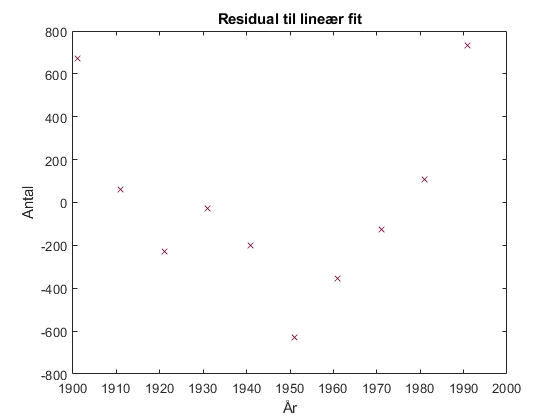

Residuals = Amount - (alpha + beta * Year);

figure(5)
plot(Year, Residuals, 'kx', 'Color', Color.DeepCleret);
title('Residual til lineær fit');
xlabel('År');
ylabel('Antal');

## 4.3 KONFIDENSINTERVAL

**Beregn et 95% konfidensinterval for hældningen.**

invers student t fordeling med frihedsgraden n - 2 = 8, og 95% konfidensinterval bestemms $t_0$ til at være som følgende.

Tzero = tinv(0.975, 8);
EmpiricalVariance = (1 / (10 - 2)) * sum((Amount - (alpha + beta * Year)).^2);

interval = Tzero * (sqrt(EmpiricalVariance) / sqrt(sum((Year - YearMean).^2)));

BetaMinus = beta - interval;
BetaPlus = beta + interval;

## 4.4 LINEARITET

**Ud fra svaret i opgave 2 og 3, vil du konkludere at antagelsen om linearitet mellem dødelighed og årstal er rimelig?**

Der er umiddelbart for få målepunkter til at kunne konkludere noget generelt. Derimod er der en lineær tendens, men residual plottet viser at residualerne systematisk ligger under 0 mellem år 1920 - 1970, desuden vil data forvente at afvige mere efter år 1991, da dødeligheder ikke kan være negative. Linearitet er ikke en god antagelse.